# Classification Assignment Live Script (Part 1 - Simple Dataset Clustering)

#### Initialization

clear; clc; close all

## Load, Partition and Normalize Data

data = readmatrix('epileptic_seizure_data.csv');
data = data(:,2:end);
[trnData, chkData, tstData] = partition_normalize(data);

## Grid Search

% Calculate characteristics potential
[ranks,weights] = relieff(data(:, 1:(end-1)), data(:, end), 10);

% Performance Matrix Indices
x = 0;  y = 0;

% Cross Validation Decision Matrix
crossValidationStats = zeros(10, 6);

% Select number of characteristics
for charNum = 2:11
    
    x = x + 1;
    y = 0;
    
    % Select cluster radius
    for clusterRadius = 0.2:0.1:0.7
        
        y = y + 1;
        
        fprintf("==============================\n\n charNum: %f, clusterRadius: %f\n", charNum, clusterRadius);

        % Data partitioning
        CVO = cvpartition(data(:, end), 'k', 5);
        
        % Cross Validation
        for i = 1:5
            
            % 5-fold Cross Validation Data partitioning
            cvTrnDataIdx = CVO.training(i);
            cvChkDataIdx = CVO.test(i);
            
            cvTrnData = data(cvTrnDataIdx, [ranks(1:charNum) size(data,2)]);
            cvChkData = data(cvChkDataIdx, [ranks(1:charNum) size(data,2)]);
            
           % Build class clusters
            [cv_c1, cv_sig1] = subclust(cvTrnData(cvTrnData(:, end) == 1,:), clusterRadius);
            [cv_c2, cv_sig2] = subclust(cvTrnData(cvTrnData(:, end) == 2,:), clusterRadius);
            [cv_c3, cv_sig3] = subclust(cvTrnData(cvTrnData(:, end) == 3,:), clusterRadius);
            [cv_c4, cv_sig4] = subclust(cvTrnData(cvTrnData(:, end) == 4,:), clusterRadius);
            [cv_c5, cv_sig5] = subclust(cvTrnData(cvTrnData(:, end) == 5,:), clusterRadius);
            cv_rulesNum = size(cv_c1, 1) + size(cv_c2, 1) + size(cv_c3, 1) + size(cv_c4, 1) + size(cv_c5, 1);

            % Construct FIS
            cv_initFIS = sugfis();

            % Configure Input - Output
            for k = 1:charNum
                cv_initFIS =  addInput(cv_initFIS, [min(data(:,k)) max(data(:,k))], Name=sprintf("in%d", k));
            end
            cv_initFIS = addOutput(cv_initFIS, [min(data(:,end)) max(data(:,end))], Name='out1');

            % Input Membership Functions
            for m = 1:size(cvTrnData, 2) - 1
                for j = 1:size(cv_c1,1)
                    %cv_initFIS = addmf(cv_initFIS, 'input', m, '', 'gaussmf', [cv_sig1(m) cv_c1(j,m)]);
                    cv_initFIS = addMF(cv_initFIS, sprintf("in%d", m), 'gaussmf', [cv_sig1(m) cv_c1(j,m)]);
                end
                for j = 1:size(cv_c2,1)
                    cv_initFIS = addMF(cv_initFIS, sprintf("in%d", m), 'gaussmf', [cv_sig2(m) cv_c2(j,m)]);
                end
                for j = 1:size(cv_c3,1)
                    cv_initFIS = addMF(cv_initFIS, sprintf("in%d", m), 'gaussmf', [cv_sig3(m) cv_c3(j,m)]);
                end
                for j = 1:size(cv_c4,1)
                    cv_initFIS = addMF(cv_initFIS, sprintf("in%d", m), 'gaussmf', [cv_sig4(m) cv_c4(j,m)]);
                end
                for j = 1:size(cv_c5,1)
                    cv_initFIS = addMF(cv_initFIS, sprintf("in%d", m), 'gaussmf', [cv_sig5(m) cv_c5(j,m)]);
                end
            end

            % Output Membership Functions
            params = [ones(1, size(cv_c1,1)) ones(1, size(cv_c2,1)) * 2 ...
                ones(1, size(cv_c3,1)) * 3  ones(1, size(cv_c4,1)) * 4  ...
                ones(1, size(cv_c5,1)) * 5];
            for m = 1:cv_rulesNum
                cv_initFIS = addMF(cv_initFIS, 'out1', 'constant', params(m), Name=sprintf("mf_%d", m));
            end

            % FIS Rule Base
            cv_ruleList = zeros(cv_rulesNum, size(cvTrnData,2));
            for m = 1:size(cv_ruleList,1)
                cv_ruleList(m,:) = m;
            end
            cv_ruleList = [cv_ruleList ones(cv_rulesNum,2)];
            cv_initFIS = addRule(cv_initFIS, cv_ruleList);

            % Train Model
            cv_anfisOptionsStruct = anfisOptions('InitialFIS', cv_initFIS, ...
                            'EpochNumber', 100, ...
                            'ValidationData', cvChkData, ...
                            'OptimizationMethod', 1);

            [~, ~, ~, ~, cv_valError] = anfis(cvTrnData, cv_anfisOptionsStruct);
                        
            % Record error stats
            crossValidationStats(x,y) = crossValidationStats(x,y) + min(cv_valError)/5;
        end
    end
end

## Plot grid search error  surface

axesX = (0.2:0.1:0.7);
axesY = (2:11);
surf(axesX, axesY, crossValidationStats);
title('Grid Search Error')
xlabel('Cluster Influence Radius');
ylabel('Features')

## Optimal Configuration Selection

[optChar, optRadius] = find(crossValidationStats == min(crossValidationStats(:)));
optChar = optChar + 1;
optRadius = 0.1 * optRadius + 0.1;

%% Select final features in data
trnData = trnData(:, [ranks(1:optChar) size(data,2)]);
chkData = chkData(:, [ranks(1:optChar) size(data,2)]);
tstData = tstData(:, [ranks(1:optChar) size(data,2)]);

## Define Final Model - Class Based Subtractive Clusterring

% Build class clusters
[c1, sig1] = subclust(trnData(trnData(:, end) == 1,:), clusterRadius);
[c2, sig2] = subclust(trnData(trnData(:, end) == 2,:), clusterRadius);
[c3, sig3] = subclust(trnData(trnData(:, end) == 3,:), clusterRadius);
[c4, sig4] = subclust(trnData(trnData(:, end) == 4,:), clusterRadius);
[c5, sig5] = subclust(trnData(trnData(:, end) == 5,:), clusterRadius);
rulesNum = size(c1, 1) + size(c2, 1) + size(c3, 1) + size(c4, 1) + size(c5, 1);

% Construct FIS
initFIS = sugfis();

% Configure Input - Output
for k = 1:optChar
    initFIS = addInput(initFIS, [min(trnData(:,k)) max(trnData(:,k))], Name=sprintf("in%d", k));
end
initFIS = addOutput(initFIS, [min(data(:,end)) max(data(:,end))], Name='out1');

% Input Membership Functions
for m = 1:size(trnData, 2) - 1
    mfCounter = 0;
    for j = 1:size(c1,1)
        %initFIS = addmf(initFIS, 'input', m, '', 'gaussmf', [sig1(m) c1(j,m)]);
        initFIS = addMF(initFIS, sprintf("in%d", m), 'gaussmf', [sig1(m) c1(j,m)], Name=sprintf("mf_%d", mfCounter + j));
    end
    mfCounter = mfCounter + size(c1,1);
    for j = 1:size(c2,1)
        initFIS = addMF(initFIS, sprintf("in%d", m), 'gaussmf', [sig2(m) c2(j,m)], Name=sprintf("mf_%d", mfCounter + j));
    end
    mfCounter = mfCounter + size(c2,1);
    for j = 1:size(c3,1)
        initFIS = addMF(initFIS, sprintf("in%d", m), 'gaussmf', [sig3(m) c3(j,m)], Name=sprintf("mf_%d", mfCounter + j));
    end
    mfCounter = mfCounter + size(c3,1);
    for j = 1:size(c4,1)
        initFIS = addMF(initFIS, sprintf("in%d", m), 'gaussmf', [sig4(m) c4(j,m)], Name=sprintf("mf_%d", mfCounter + j));
    end
    mfCounter = mfCounter + size(c4,1);
    for j = 1:size(c5,1)
        initFIS = addMF(initFIS, sprintf("in%d", m), 'gaussmf', [sig5(m) c5(j,m)], Name=sprintf("mf_%d", mfCounter + j));
    end
end

% Output Membership Functions
params = [ones(1, size(c1,1)) ones(1, size(c2,1)) * 2 ...
    ones(1, size(c3,1)) * 3  ones(1, size(c4,1)) * 4  ...
    ones(1, size(c5,1)) * 5];
for m = 1:rulesNum
    initFIS = addMF(initFIS, 'out1', 'constant', params(m), Name=sprintf("mf_%d", m));
end

% FIS Rule Base
ruleList = zeros(rulesNum, size(trnData,2));
for m = 1:size(ruleList,1)
    ruleList(m,:) = m;
end
ruleList = [ruleList ones(rulesNum,2)];
initFIS = addRule(initFIS, ruleList);

anfisOptionsStruct = anfisOptions('InitialFIS', initFIS, ...
                'EpochNumber', 300, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

## Train Model

[finalFIS, trainError, ~, valFIS, valError] = anfis(trnData, anfisOptionsStruct);

% Make Predictions & Round Data
rawY = evalfis(tstData(:,1:end-1), valFIS);
Y = round(rawY);
Y(Y < min(data(:,end))) = min(data(:,end));
Y(Y > max(data(:,end))) = max(data(:,end));

## Benchmarking and Graphing

#### Calculate performance metrics

[errorMat, accuracy, producerAcc, userAcc, k] = metrics(tstData, Y);

#### Stats, Learning Curves, Final MFs

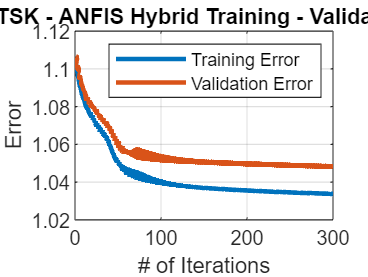

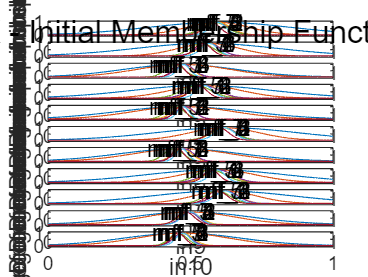

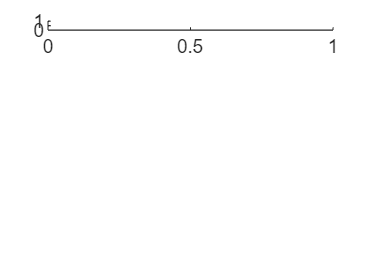

Error using fuzzy.internal.utility.validCharOrString
Input membership function name must be a character row vector or a string scalar having nonempty character contents.

Error in fuzzy.internal.utility.validateFIS (line 140)
        fuzzy.internal.utility.validCharOrString(...

Error in plotmf (<a hre

stats_graphs(valFIS, initFIS, chkData, trainError, valError);


% Predictions - Data Plot (Raw Y)
tstY = [tstData(:, end) rawY];
tstY = sortrows(tstY);
figure
plot(tstY(:,1), '-b', 'LineWidth', 2.5)
hold on
plot(tstY(:,2), '.r')
title('Predictions vs Actual Data');
ylabel('Value');
xlabel('Dataset Entry');

% Predictions - Data Plot (Rounded Y)
tstY = [tstData(:, end) Y];
tstY = sortrows(tstY);
figure
plot(tstY(:,1), '-b', 'LineWidth', 2.5)
hold on
plot(tstY(:,2), '.r')
title('Predictions vs Actual Data');
ylabel('Value');
xlabel('Dataset Entry');

% Grid Search Error Surface
X = (0.2:0.1:0.6);
Y = (3:10);
figure
surf(X, Y, crossValidationStats);
xlabel('Cluster Influence Range')
ylabel('Number of Features')
zlabel('RMSE')
title('Grid Search Error')